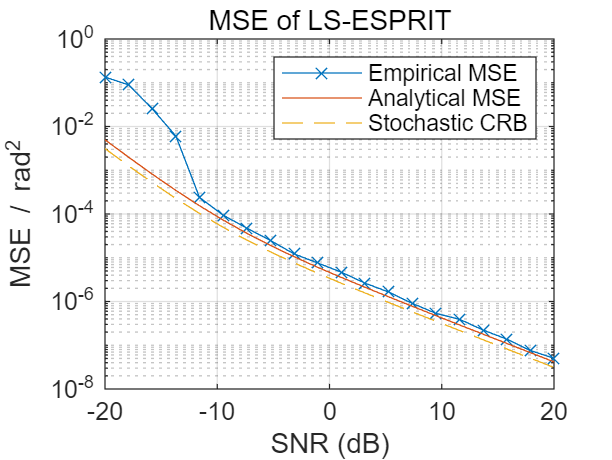

% performance evaluation of ULA-based ESPRIT
clear(); close all;

% set up
wavelength = 1; % normalized
d = wavelength / 2;
n_elements = 10; % number of elements in ULA
design = design_array_1d('ula', n_elements, d);
doas = linspace(-pi/3, pi/3, 6); % 4 sources
power_source = 1;
snapshot_count = 500; % increased for better asymptotic behavior
source_count = length(doas);
k = 2*pi*design.element_spacing/wavelength; % normalized wave number for ESPRIT

% we vary SNR from -20dB to 20dB
n_param_power_noise = 20;
param_power_noise = 10.^(-linspace(-20, 20, n_param_power_noise)/10);
n_repeat = 200;
mse_em = zeros(n_param_power_noise, 1);
mse_an = zeros(n_param_power_noise, 1);
crb = zeros(n_param_power_noise, 1);
snr = zeros(n_param_power_noise, 1);

for ii = 1:n_param_power_noise
    power_noise = param_power_noise(ii);
    snr(ii) = 10*log10(power_source / power_noise);
    cur_se = 0;
    valid_count = 0;
    for rr = 1:n_repeat
        [~, R, ~] = snapshot_gen_sto(design, doas, wavelength, snapshot_count, power_noise, power_source);
        sp = esprit_1d(R, source_count, k, 'Unit', 'radian', 'Formulation', 'LS', 'RowWeights', 'Off');
        if sp.resolved && ~isempty(sp.x_est)
            % match estimated DOAs to true DOAs
            est_doas = sp.x_est;
            true_doas = doas;
            matched_est = zeros(1, source_count);
            for j = 1:source_count
                [~, idx] = min(abs(est_doas - true_doas(j)));
                matched_est(j) = est_doas(idx);
                est_doas(idx) = Inf; % prevent reuse
            end
            cur_se = cur_se + sum((matched_est - doas).^2);
            valid_count = valid_count + 1;
        end
    end
    if valid_count > 0
        mse_em(ii) = cur_se / (source_count * valid_count);
    else
        mse_em(ii) = NaN; % mark as invalid if no successful estimates
    end
    mse_an(ii) = mean(ecov_esprit_1d(design, wavelength, doas, power_source, power_noise, snapshot_count, 'DiagonalsOnly'));
    crb(ii) = mean(diag(crb_uc_sto_1d(design, wavelength, doas, power_source, power_noise, snapshot_count)));
end
fprintf('\n');

% plot
semilogy(snr, mse_em, '-x', snr, mse_an, '-', snr, crb, '--');
xlabel('SNR (dB)'); ylabel('MSE / rad^2'); grid on;
legend('Empirical MSE', 'Analytical MSE', 'Stochastic CRB');
title('MSE of LS-ESPRIT');